 clear ur;
 ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e')

ur =   urRTDEClient with properties:

            CobotName: 'universalUR5e'
       URControllerIP: '192.168.1.10'
    ControllerVersion: '5.11.10.0'
        RTDEFrequency: 125
    ConnectionTimeOut: 10
        RigidBodyTree: [1×1 rigidBodyTree]


% % Cargamos una pose de prueba
 testPose = rad2deg(readJointConfiguration(ur)');
 
% % Cargamos una foto de prueba a su vez
 [imgdata,img] = fotosw()

imgdata = 480×640×3 uint8 array
imgdata(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   252   254   254   255   255   255   250   251   252   253   255   255   254   252   255   249   233   198   158   133   131   142   128   133   119    91    97   111   112   115  

img = "actualphoto.jpg"

 testImage = imgdata; 

% testPose = [88.8605 -62.3678 -78.9178 -128.9287 91.3690 -173.4337]'
% testImage = imread("actualPhoto.jpg")

undistortedTestImage = undistortImage(testImage,ld.cameraParams);

%Calculamos la transoformada de la base al efector final de la pose anterior
testPoseRad = deg2rad(testPose);
endEffectorToBaseTformTest = getTransform(robotModel,testPoseRad,"flange");

% Especificamos la familia a la que pertenece el AprilTag.
tagFamily = "tag36h11"; %<<<<<--------------------CAMBIAR ESTO
tagSize = .049; % AprilTag size in meters

% Detectamos el AprilTag en la imagen
[~,~,aprilTagToCameraTform] = readAprilTag(undistortedTestImage,"tag36h11",intrinsics,tagSize);

%Encontramos la transformada de la base del robot a la camara
cameraToBaseTestTform = rigidtform3d(endEffectorToBaseTformTest * cameraToEndEffectorTform.A);

%Encontramos la transformada de la base del robot al AprilTag
tagToBaseTestTform = cameraToBaseTestTform.A * aprilTagToCameraTform.A;
cubePosition = tagToBaseTestTform(1:3,4)

cubePosition =    -0.0233
    0.6221
   -0.0905


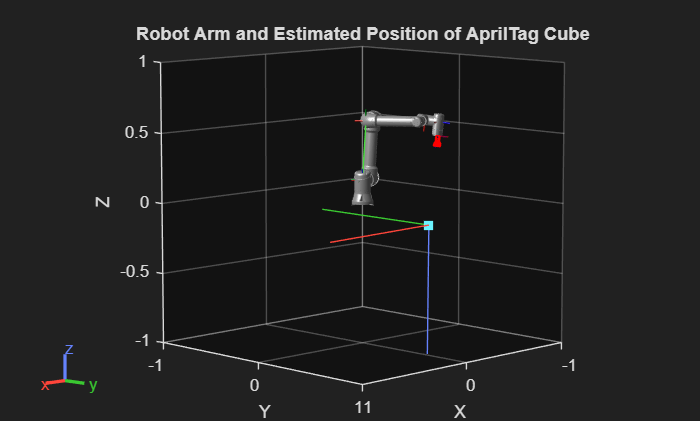

% Mostramos el modelo del robot
show(robotModel,testPoseRad);
hold on
rotate3d("on")
%Mostramos las posiciones estimadas y orientaciones de la camara y el cubo
plotCamera(AbsolutePose = cameraToBaseTestTform, Opacity=0, size=0.02)
scatter3(cubePosition(1), cubePosition(2), cubePosition(3), 50, 'square', 'filled')
cubeRotationQuaternion = rotm2quat(tagToBaseTestTform(1:3,1:3));
plotTransforms(cubePosition', cubeRotationQuaternion)
title("Robot Arm and Estimated Position of AprilTag Cube")
xlim([-1,1])
ylim([-1, 1])
zlim([-1,1])